clc;
clear all;
close all;

## **Project 4: Implementing a Variational Autoencoder (VAE) to generate images of digits between 0 and 9.**

## Importing training and testing data. 

warning('off')
addpath('./functions');
addpath('./data');
trainImagesFile = 'train-images.idx3-ubyte';
trainLabelsFile = 'train-labels.idx1-ubyte';
testImagesFile = 't10k-images.idx3-ubyte';
testLabelsFile = 't10k-labels.idx1-ubyte';

`Read MNIST image data`

training_images = processMNISTimages(trainImagesFile);


Read MNIST image data...
Number of images in the dataset:  60000 ...


test_images = processMNISTimages(testImagesFile);


Read MNIST image data...
Number of images in the dataset:  10000 ...


train_labels = processMNISTlabels(trainLabelsFile);


Read MNIST label data...
Number of labels in the dataset:  60000 ...


test_labels = processMNISTlabels(testLabelsFile);


Read MNIST label data...
Number of labels in the dataset:  10000 ...


## **Basic test for parameters**

Now, we need to design the encoder and the decoder for our network. The encoder part consist of normal convolutional neural network part, taking the image and passing it to the multiple conv layers, relu and finally to the fully connected layer to form the 2-D latent space. Then, designing the decoder part where we using the `transposedConv2dLayer `for decoding the datas from the model. 

fprintf('test case 1- Basic test for parameters ')

test case 1- Basic test for parameters 


latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);


Using dlnetwork to converts a layer graph to a `dlnetwork` object representing a deep neural network for custom training loops.

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);


**Training the network**

Next, we creating a function called `run_training `to train the model using a custom training loop.

For each iteration in an epoch:

- Obtain the next mini-batch from the training set.

- Convert the mini-batch to a `dlarray` object, making sure to specify the dimension labels `'SSCB'` (spatial, spatial, channel, batch).

- For GPU training, convert the `dlarray` to a `gpuArray` object.

- Evaluate the model gradients using the `dlfeval` and `modelGradients` functions.

- Update the network learnables and the average gradients for both networks, using the `adamupdate` function.

At the end of each epoch, pass the test set images through the autoencoder, and display the loss and the training time for that epoch.

numEpochs = 30;
lr = 1e-3;
momentum = 1;

[encoderNet1, decoderNet1] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, training_images, test_images);

Epoch : 1 Test ELBO loss = 28.5922. Time taken for epoch = 11.7574s 
Epoch : 2 Test ELBO loss = 26.6035. Time taken for epoch = 10.0265s 
Epoch : 3 Test ELBO loss = 25.845. Time taken for epoch = 9.7697s 
Epoch : 4 Test ELBO loss = 25.3627. Time taken for epoch = 9.44s 
Epoch : 5 Test ELBO loss = 25.1033. Time taken for epoch = 9.537s 
Epoch : 6 Test ELBO loss = 24.5551. Time taken for epoch = 9.355s 
Epoch : 7 Test ELBO loss = 23.9819. Time taken for epoch = 9.3297s 
Epoch : 8 Test ELBO loss = 23.6498. Time taken for epoch = 9.3239s 
Epoch : 9 Test ELBO loss = 23.4825. Time taken for epoch = 9.5418s 
Epoch : 10 Test ELBO loss = 23.3664. Time taken for epoch = 9.3598s 
Epoch : 11 Test ELBO loss = 23.2079. Time taken for epoch = 9.4073s 
Epoch : 12 Test ELBO loss = 23.0837. Time taken for epoch = 9.391s 
Epoch : 13 Test ELBO loss = 22.9619. Time taken for epoch = 9.3715s 
Epoch : 14 Test ELBO loss = 22.8162. Time taken for epoch = 9.4025s 
Epoch : 15 Test ELBO loss = 22.7925. Time taken

**visualization**

To visualize and interpret the results, using the below function. This function shows a randomly chosen digit from each class accompanied by its reconstruction after passing through the autoencoder.

Using The `VisualizeLatentSpace` function, We can then visualize the latent space defined by the means and the variances in the two dimensions. 

The Generate function initializes new encodings sampled from a normal distribution, and outputs the images generated when these encodings pass through the decoder network.

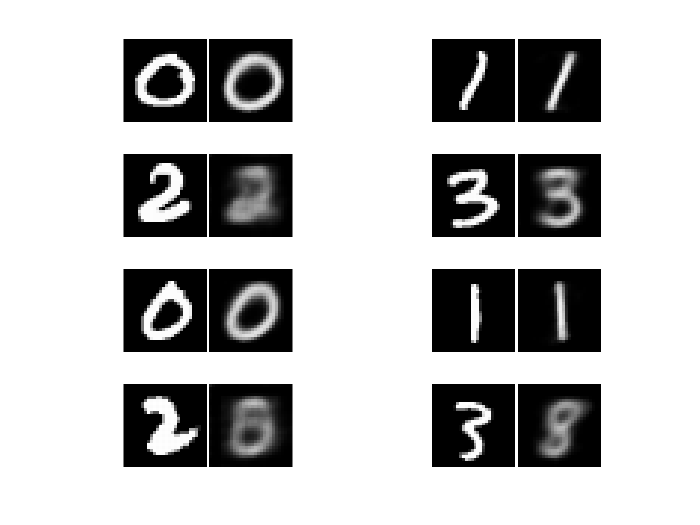

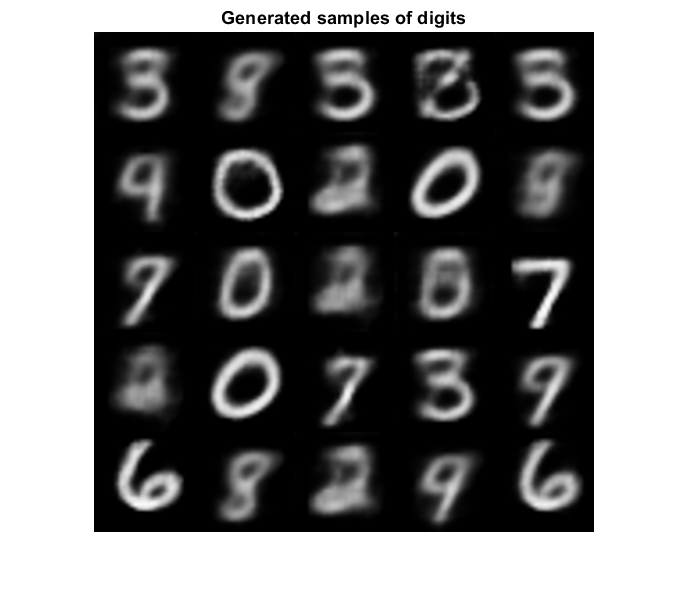


visualizeReconstruction(test_images, test_labels, encoderNet1, decoderNet1)

generate(decoderNet1, latentDim)

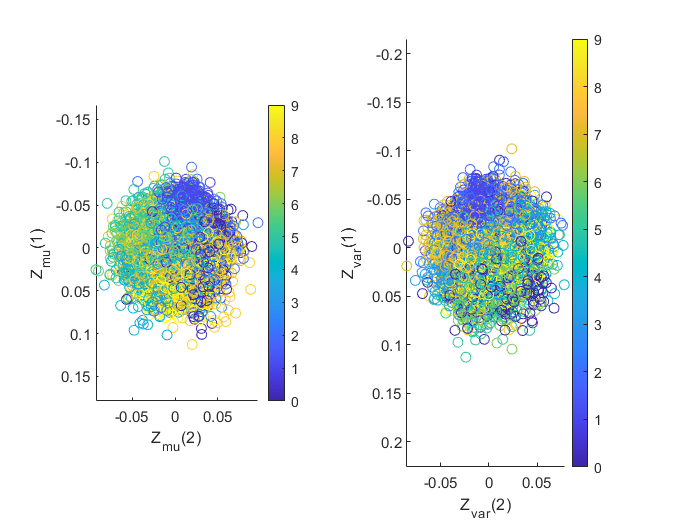


visualizeLatentSpace(test_images, test_labels, encoderNet)

**Test trail 2**

In this test, I am **increasing the no of conv layers** on the encoder part and the other parameters remains same.

fprintf('test case 2- increasing the no of conv layers ')
latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);
encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

numEpochs = 20;
lr = 1e-3;
momentum = 1;

[encoderNet2, decoderNet2] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, training_images, test_images);
visualizeReconstruction(test_images, test_labels, encoderNet2, decoderNet2)

generate(decoderNet2, latentDim)

visualizeLatentSpace(test_images, test_labels, encoderNet)

**Test case 3**

 In this test case, I am Making** the learning rate to be less** and making other things same. 

fprintf('test case 3- the learning rate to be less')
latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);
encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

numEpochs = 20;
lr = 1e-4;
momentum = 1;

[encoderNet2, decoderNet2] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, training_images, test_images);
visualizeReconstruction(test_images, test_labels, encoderNet2, decoderNet2)

generate(decoderNet2, latentDim)

visualizeLatentSpace(test_images, test_labels, encoderNet)


**Test case 4**

 In this test case, I am Making the **momentum to be zero**, learning rate to 0.001 and making other things same.

fprintf('test case 4-momentum to be zero')

latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);
encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

numEpochs = 20;
lr = 1e-3;
% momentum = 0;

[encoderNet2, decoderNet2] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, training_images, test_images);
visualizeReconstruction(test_images, test_labels, encoderNet2, decoderNet2)

generate(decoderNet2, latentDim)

visualizeLatentSpace(test_images, test_labels, encoderNet)


**Test case 5**

 In this test case, I am Making the** No of epochs to be less**, learning rate to 0.001,momentum to 1 and making other things same.

fprintf('test case 5- No of epochs to be less')
latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);
encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

numEpochs = 10;
lr = 1e-3;
momentum = 1;

[encoderNet2, decoderNet2] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, training_images, test_images);
visualizeReconstruction(test_images, test_labels, encoderNet2, decoderNet2)

generate(decoderNet2, latentDim)

visualizeLatentSpace(test_images, test_labels, encoderNet)


**Test case 6**

 In this test case, I am introducing a **drop out layer** in the encoder section

fprintf('test case 6-drop out layer in the encoder section')
latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    dropoutLayer('Name','drop1')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);
encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

numEpochs = 15;
lr = 1e-3;
momentum = 1;

[encoderNet2, decoderNet2] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, training_images, test_images);
visualizeReconstruction(test_images, test_labels, encoderNet2, decoderNet2)

generate(decoderNet2, latentDim)

visualizeLatentSpace(test_images, test_labels, encoderNet)




**Test case 7**

 In this test case, I am introducing a **drop out layer** in the encoder and decorder section with 30 iteration

fprintf('test case 7-drop out layer in the encoder and decorder with section 30')
latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    dropoutLayer('Name','drop1')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    dropoutLayer('Name','drop1')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);
encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

numEpochs = 30;
lr = 1e-3;
momentum = 1;

[encoderNet2, decoderNet2] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, training_images, test_images);
visualizeReconstruction(test_images, test_labels, encoderNet2, decoderNet2)

generate(decoderNet2, latentDim)

visualizeLatentSpace(test_images, test_labels, encoderNet)


**Test case 8**

 In this test case, I am introducing a **drop out layer** in the encoder and decorder section with 40 iteration

fprintf('test case 8-drop out layer in the encoder and decorder with section 40')
latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    dropoutLayer('Name','drop1')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    dropoutLayer('Name','drop1')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);
encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

numEpochs = 40;
lr = 1e-3;
momentum = 1;

[encoderNet2, decoderNet2] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, training_images, test_images);
visualizeReconstruction(test_images, test_labels, encoderNet2, decoderNet2)

generate(decoderNet2, latentDim)

visualizeLatentSpace(test_images, test_labels, encoderNet)



**Test case 9**

 In this test case, I am making learning rate to 0.01 


fprintf('test case 9-learning rate to 0.01')
latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    dropoutLayer('Name','drop1')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    dropoutLayer('Name','drop1')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);
encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

numEpochs = 20;
lr = 1e-2;
momentum = 1;

[encoderNet2, decoderNet2] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, training_images, test_images);
visualizeReconstruction(test_images, test_labels, encoderNet2, decoderNet2)

generate(decoderNet2, latentDim)

visualizeLatentSpace(test_images, test_labels, encoderNet)



**Test case 10**

 In this test case, I am giving some higher weights to KL divergence term(1.5)


fprintf('test case 10- higher weights to KL divergence term(1.5)')
latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    dropoutLayer('Name','drop1')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    dropoutLayer('Name','drop1')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);
encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

numEpochs = 20;
lr = 1e-3;
momentum = 1;

[encoderNet2, decoderNet2] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, training_images, test_images);
visualizeReconstruction(test_images, test_labels, encoderNet2, decoderNet2)

generate(decoderNet2, latentDim)

visualizeLatentSpace(test_images, test_labels, encoderNet)




**Test case 11**

 In this test case, I am giving some higher weights to KL divergence term(1.5)


fprintf('test case 11- higher weights to KL divergence term(1.5) without dropout')
latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
   % dropoutLayer('Name','drop1')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
   % dropoutLayer('Name','drop1')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);
encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

numEpochs = 20;
lr = 1e-3;
momentum = 1;

[encoderNet2, decoderNet2] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, training_images, test_images);
visualizeReconstruction(test_images, test_labels, encoderNet2, decoderNet2)

generate(decoderNet2, latentDim)

visualizeLatentSpace(test_images, test_labels, encoderNet)






**Test case 12**

 In this test case, I am giving 5D latent space.


fprintf('test case 12- 5D latent space')
latentDim = 5;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
   % dropoutLayer('Name','drop1')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
   % dropoutLayer('Name','drop1')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);
encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

numEpochs = 20;
lr = 1e-3;
momentum = 1;

[encoderNet2, decoderNet2] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, training_images, test_images);
visualizeReconstruction(test_images, test_labels, encoderNet2, decoderNet2)

generate(decoderNet2, latentDim)

visualizeLatentSpace(test_images, test_labels, encoderNet)



**Advanced part**

numTrainImages = size(training_images,4);

layers = better_cnn_classifier()

layers =   10x1 Layer array with layers:

     1   ''   Image Input             28x28x1 images with 'zerocenter' normalization
     2   ''   Convolution             20 5x5 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Convolution             20 5x5 convolutions with stride [1  1] and padding [0  0  0  0]
     6   ''   ReLU                    ReLU
     7   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   ''   Fully Connected         10 fully connected layer
     9   ''   Softmax                 softmax
    10   ''   Classification Output   crossentropyex


% Defining the other half of MNIST data to be training on
MNIST_n = numTrainImages;

MNIST_images_train1 = extractdata(training_images(:,:,1,1:MNIST_n));
MNIST_labels_train1 = train_labels(1:MNIST_n);
images_test = extractdata(test_images(:,:,1,1:10000));
labels_test = test_labels(1:10000);


options = trainingOptions('adam',...
        'MaxEpochs',5);

% Training the classifier on MNIST data alone to check for 90%+ accuracy
net = trainNetwork(training_images, train_labels,layers, options);   

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       10.16% |       2.3215 |          0.0010 |
|       1 |          50 |       00:00:00 |       85.16% |       0.4728 |          0.0010 |
|       1 |         100 |       00:00:01 |       90.63% |       0.2953 |          0.0010 |
|       1 |         150 |       00:00:02 |       93.75% |       0.1774 |          0.0010 |
|       1 |         200 |       00:00:03 |       96.09% |       0.1457 |          0.0010 |
|       1 |         250 |       00:00:03 |       97.66% |       0.1358 |          0.0010 |
|       1 |         300 |  


% Also training it with only the second half of MNIST data for comparison 
% net = trainNetwork(MNIST_images_train2, MNIST_labels_train2,classifier_layers, options);    

predicted_labels = classify(net, images_test);
Accuracy = sum(labels_test == predicted_labels)/numel(labels_test);
disp(['Accuracy acheived on test set : ' num2str(Accuracy)])

Accuracy acheived on test set : 0.9847



numTrainImages = size(training_images,4);

layers = better_cnn_classifier()

layers =   10x1 Layer array with layers:

     1   ''   Image Input             28x28x1 images with 'zerocenter' normalization
     2   ''   Convolution             20 5x5 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Convolution             20 5x5 convolutions with stride [1  1] and padding [0  0  0  0]
     6   ''   ReLU                    ReLU
     7   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   ''   Fully Connected         10 fully connected layer
     9   ''   Softmax                 softmax
    10   ''   Classification Output   crossentropyex


% Defining the other half of MNIST data to be training on
MNIST_n = numTrainImages/2;

MNIST_images_train1 = extractdata(training_images(:,:,1,1:MNIST_n));
MNIST_labels_train1 = train_labels(1:MNIST_n);
images_test = extractdata(test_images(:,:,1,1:10000));
labels_test = test_labels(1:10000);


% p% of data will be used from the other half of MNIST train data
percent = 1;
Extended = percent*(MNIST_n);
MNIST_images_train2 = training_images(:,:,1,MNIST_n+1:MNIST_n+Extended);
MNIST_labels_train2 = train_labels(MNIST_n+1:MNIST_n+Extended);

% p% VAE generated images
count = 1;
for i = 1:(Extended/10)  % Rest of the images/10
    for c=0:9
        idx = MNIST_labels_train2 == categorical(c);
        idx = find(idx);
        idx = idx(randi(numel(idx),1));
        
        X = MNIST_images_train2(:,:,:,idx);

        [z, ~, ~] = sampling(encoderNet, X);
        % Random noise added to the latent representation
        randomNoise = dlarray(randn(1,1,latentDim,1),'SSCB');
        z = z + randomNoise;
        
        XPred = sigmoid(forward(decoderNet, z));
        
%         X = gather(extractdata(X));
        generatedImages(:,:,1,count) = extractdata(XPred);
        generatedLabels(count) = MNIST_labels_train2(idx);
        count = count+1;
    end
end

% Training the classfier on MNIST data + generated images
images_train = cat(4,MNIST_images_train2(:,:,1,1:Extended),double(generatedImages));
labels_train = [MNIST_labels_train2(1:Extended);generatedLabels'];   

% Training the classifier on just the generated images
%images_train = double(generatedImages);
%labels_train = generatedLabels.';   

options = trainingOptions('adam',...
        'MaxEpochs',10,...
        'ValidationData',{images_test,labels_test});

net = trainNetwork(images_train,labels_train,better_cnn_classifier,options);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       11.72% |       11.22% |       2.3071 |       2.2972 |          0.0010 |
|       1 |          50 |       00:00:01 |       39.06% |       81.81% |       1.6195 |       0.6975 |          0.0010 |
|       1 |         100 |       00:00:02 |       50.00% |       90.24% |       1.2884 |       0.3330 |          0.0010 |
|       1 |         150 |       00:00:03 |       50.78% |       92.33% |       1.3501 |   


% Testing the classifier
predicted_labels = classify(net, images_test);
Accuracy = sum(labels_test == predicted_labels)/numel(labels_test);
disp(['Accuracy acheived on test set : ' num2str(Accuracy)])

Accuracy acheived on test set : 0.9869
